# lora sim script

## lora parameters

clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=84;
randomData=true;
%channel
perfectChannel=true;%no doppler or awgn
maxDopplerShift=0;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=25; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
loopDoppler=false;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    messageBits=ones(dataLength,1);
end
%generate lora signal
loraSignal=generateLoraSignal(messageBits,SF,numSym);

symbolBits =      1     1     1     0     0     0     1     1     1     0     1     0     0     1     0     1     1     0     0     1     1     0     1     1     0     0     1     1     1     0     1     0     0     1     1     0     1     0     0     0     0     1     1     1     1     1     0     0     0     0
     1     0     1     1     1     1     1     1     0     1     0     1     0     0     0     0     1     0     1     0     0     0     0     1     0     1     1     0     1     0     1     0     0     0     0     0     1     1     0     1     0     0     0     1     0     1     1     0     0     1
     0     1     1     1     1     0     1     0     1     1     1     0     0     0     1     0     1     1     0     0     0     1     0     0     0     0     1     0     1     0     1     0     1     1     0     0     1     0     0     1     0     1     1     0     1     0     1     0     1     0
     1     1     1     0     1     0     0     0     0     0     0     1     1     0

decimalSymbols =         3351        2831        3945        1751        2006        1141        3767        3085        2808        1651        2592        1401         476        2061         843        2195        3831         703        1248        2229        2161        1019        2549        3504         372        1140        3729        2508        3661         201        3985          96         871        2763        2484         457        4094        1245         230        1669         289        2761        2616        3328        2768        3559        1574         112         977        1033


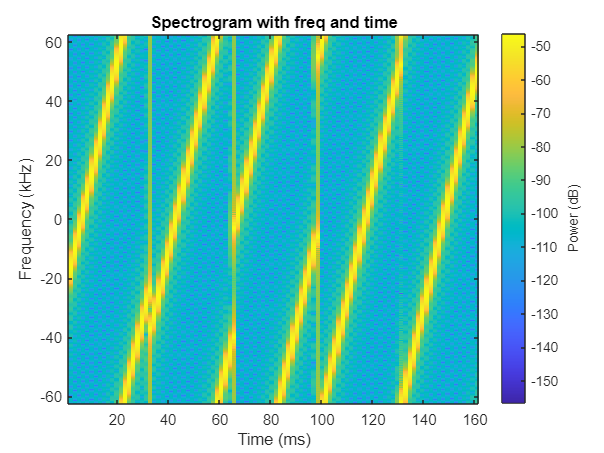


%spectroram of first 5 symbols
figure
windowLength=round((SPS)/10);
spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
title('Spectrogram with freq and time')

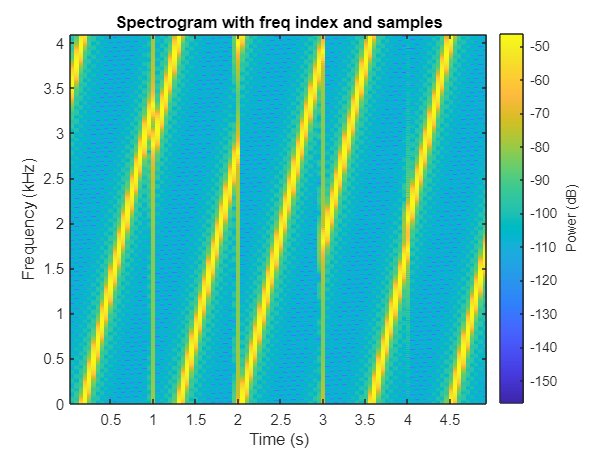

figure
spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
title('Spectrogram with freq index and samples')

## channel

 if perfectChannel
     rxSignal=loraSignal;
 else

 end

## rx



decodedBits=demodulateLoraSignal(rxSignal,SF,numSym);

dechirpedSymbols =         3351        2831        3945        1751        2006        1141        3767        3085        2808        1651        2592        1401         476        2061         843        2195        3831         703        1248        2229        2161        1019        2549        3504         372        1140        3729        2508        3661         201        3985          96         871        2763        2484         457        4094        1245         230        1669         289        2761        2616        3328        2768        3559        1574         112         977        1033


## ber

errors=sum(messageBits~=decodedBits)

errors = 0